# **QIBC analysis**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\A59_Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'U2OS DMSO',[2],2:3,1:25,[0 0 0]; %1    
        'U2OS DOX',[2],4:11,1:25,[0 0 0]; %1    


    };


% load([dataDir 'sensordata.mat'],'S');
S = loadData_IF(conditions, dataDir);


**PCNA vs EdU levels early S cells**

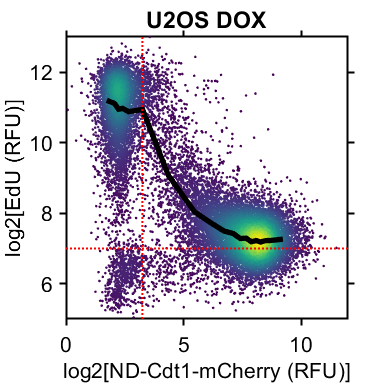

ans = 19866

conds=[2];

xval = 'mCherry2';
yval = 'FarRed1';
                      


for i = 1:length(conds)
condition = conds(i);
xdata = log2(S(condition).(xval)); 
ydata =  log2(S(condition).(yval));

inds = log2(S(condition).dna) < 20.25 & S(condition).FITC1 > 2^7.5;
xdata = xdata(inds);
ydata = ydata(inds);

    
    %     edges = linspace(5,10,20);
    edges = prctile(xdata,linspace(2.5,97.5,20));
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','std'},...
        'Edges',edges);
    midpoints = edges;
    midpoints = (midpoints(1:end-1) + midpoints(2:end))/2 ;
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    colormap('viridis')
    dscatter(xdata,ydata,'MSIZE',4,'MARKER','o');
    patchline(midpoints(binData(1).numCells > 10),binData(1).median(binData(1).numCells > 10),'LineWidth',4,'EdgeAlpha',1)
        
    xlim([0 12])
    ylim([5 13])
        vline((3.25),'r:');
    hline(7,'r:');
    axis square
    ylabel('log2[EdU (RFU)]');
    xlabel('log2[ND-Cdt1-mCherry (RFU)]');
%     set(gca,'FontSize',8)
    box on
    title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');
        print_pdf([pwd() '\Figs\Cdt1vsEdU.pdf'])
    length(xdata)

end